# 02686 - Scientific Computing for Differential Equations - Exam 4 - Solvers for SDEs 

## Multivariate Standard Wiener Process

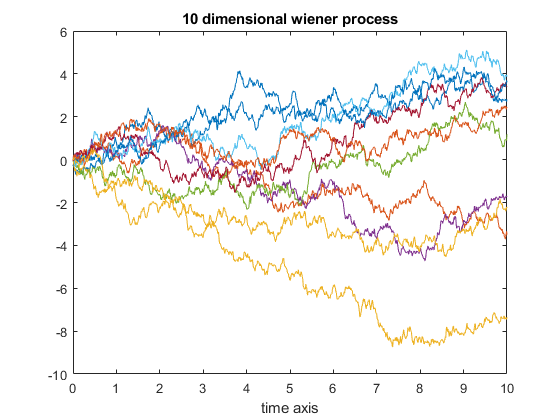

T_end = 10;
n = 1000;
n_w = 10;
dt = sqrt(T_end/n);
t = linspace(0,T_end,n);

[w] = wiener(n,n_w,dt)';

plot(t,w);
title("10 dimensional wiener process");
xlabel("time axis");

## Explicit explicit method with fixed step size

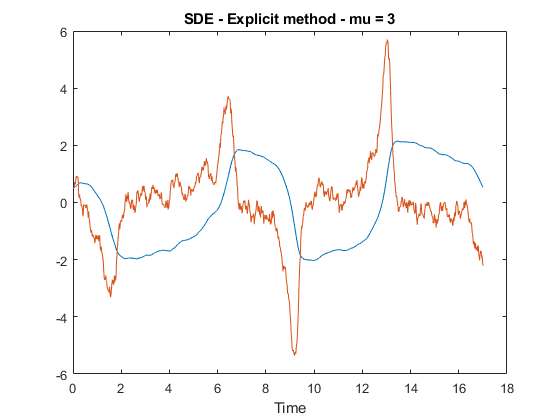

T_end = 17;
n = 1000;
n_w = 10;
dt = sqrt(T_end/n);

T = linspace(0,T_end,n);

w = wiener(n,1,dt);
x0 = [0.5 0.5];

mu = 3;
sigma = 1;
p = [mu, sigma];

[X,dt] = SDEsolverExplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X2 = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);

plot(T,X);
xlabel("Time");
title("SDE - Explicit method - mu = 3")

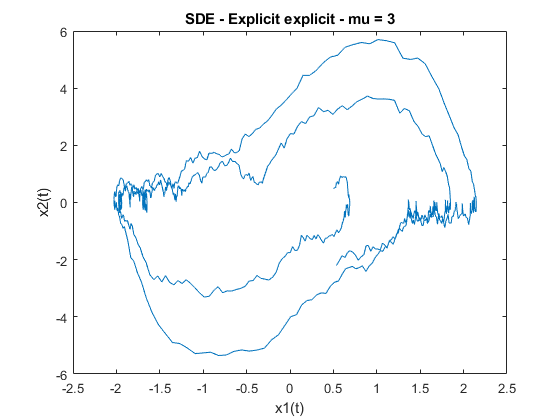

plot(X(1,:),X(2,:))
xlabel('x1(t)')
ylabel('x2(t)')
title('SDE - Explicit explicit - mu = 3')

## Implicit

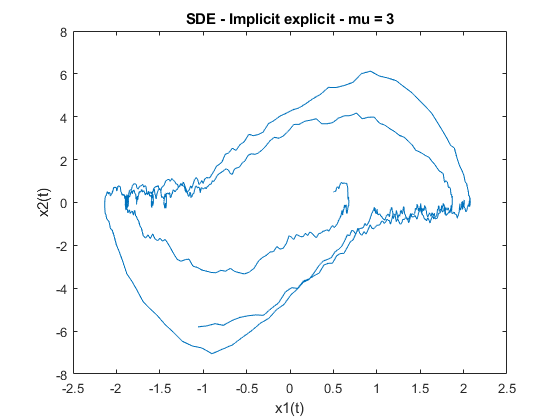

plot(X2(1,:),X2(2,:))
xlabel('x1(t)')
ylabel('x2(t)')
title('SDE - Implicit explicit - mu = 3')

## Average

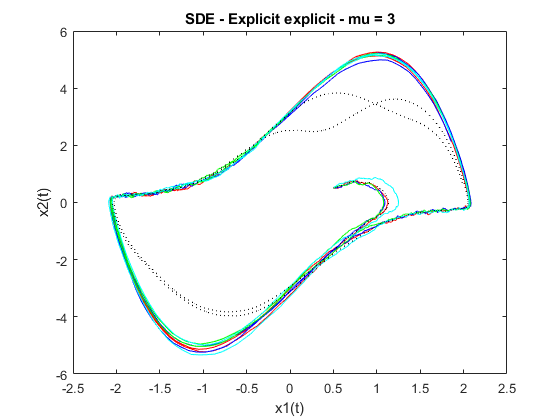

X_average = zeros(2,n,4);

w = wiener(n,1,dt);
[X,dt] = SDEsolverExplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,1) = X;
plot(X(1,:),X(2,:),"r")
hold on;
w = wiener(n,1,dt);
[X,dt] = SDEsolverExplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,2) = X;
plot(X(1,:),X(2,:),"b")
hold on;
w = wiener(n,1,dt);
[X,dt] = SDEsolverExplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,3) = X;
plot(X(1,:),X(2,:),"g")
hold on;
w = wiener(n,1,dt);
[X,dt] = SDEsolverExplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,4) = X;
plot(X(1,:),X(2,:),"c")
hold on;
X_ = mean(X_average,3);
plot(X_(1,:),X_(2,:),":k")
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('SDE - Explicit explicit - mu = 3')

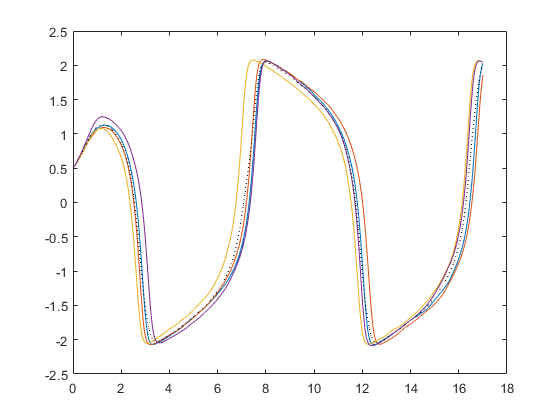

plot(T,X_average(1,:,1));
hold on;
plot(T,X_average(1,:,2));
hold on;
plot(T,X_average(1,:,3))
hold on;
plot(T,X_average(1,:,4))
hold on;
plot(T,X_(1,:),":k")
hold off;

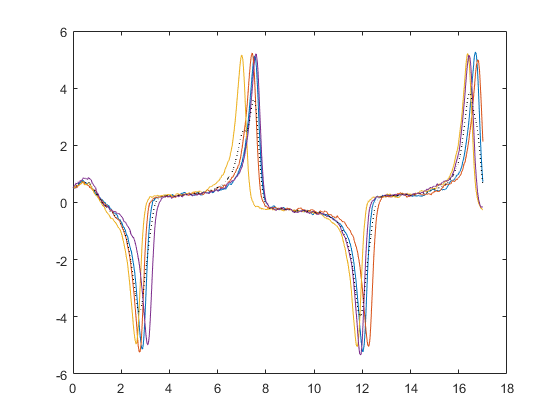

plot(T,X_average(2,:,1));
hold on;
plot(T,X_average(2,:,2));
hold on;
plot(T,X_average(2,:,3))
hold on;
plot(T,X_average(2,:,4))
hold on;
plot(T,X_(2,:),":k")
hold off;

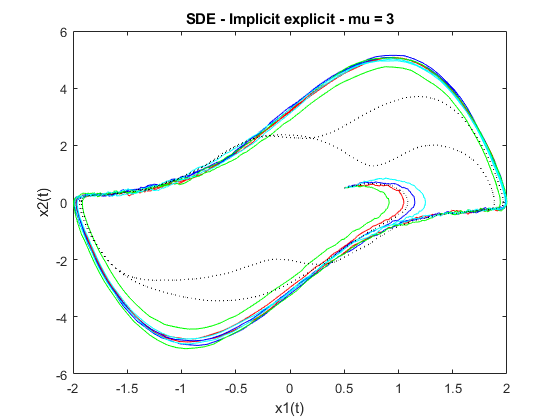

% Implicit explicit

X2 = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);

X_average = zeros(2,n,4);

w = wiener(n,1,dt);
[X] = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,1) = X;
plot(X(1,:),X(2,:),"r")
hold on;
w = wiener(n,1,dt);
[X] = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,2) = X;
plot(X(1,:),X(2,:),"b")
hold on;
w = wiener(n,1,dt);
[X] = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,3) = X;
plot(X(1,:),X(2,:),"g")
hold on;
w = wiener(n,1,dt);
[X] = SDEsolverImplicitExplicit(@VanderpolDrift,@VanderPolDiffusion1,T,x0,w,p);
X_average(:,:,4) = X;
plot(X(1,:),X(2,:),"c")
hold on;
X_ = mean(X_average,3);
plot(X_(1,:),X_(2,:),":k")
hold off
xlabel('x1(t)')
ylabel('x2(t)')
title('SDE - Implicit explicit - mu = 3')